3.2 **Line Finding using Hough Transform**

In the section, the goal is to extract the long edge of the path in the `macritchie.jpg’ image as a consistent line using the Hough transform.

a) Reuse the edge image computed via the Canny algorithm with sigma=1.0.

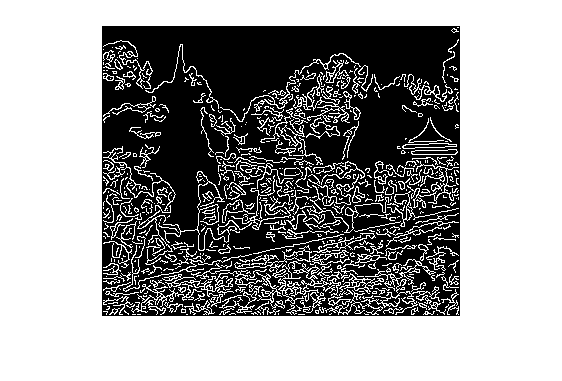

originalImage = imread('images/macritchie.jpg');
image = rgb2gray(originalImage);

tl = 0.04;
th = 0.1;
sigma = 1.0;

edgeImage = edge(image, 'Canny', [tl, th], sigma);
imshow(edgeImage);

b) As there is no function available to compute the Hough transform in MATLAB, we will use the Radon transform, which for binary images is equivalent to the Hough transform. Read the help manual on Radon transform, and explain why the transforms are equivalent in this case. When are they different?

**TODO**

>> [H, xp] = radon(E);

Display H as an image. The Hough transform will have horizontal bins of angles corresponding to 0-179 degrees, and vertical bins of radial distance in pixels as captured in xp. The transform is taken with respect to a Cartesian coordinate system where the origin is located at the centre of the image, and the x-axis pointing right and the y-axis pointing up.

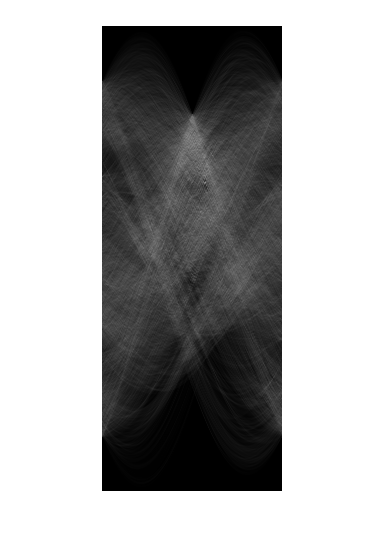

[houghImage, radialCoordinates] = radon(edgeImage);
imshow(uint8(houghImage));

c) Find the location of the maximum pixel intensity in the Hough image in the form of [theta, radius]. These are the parameters corresponding to the line in the image with the strongest edge support.

% [intensity, location] = max(houghImage(:));

% https://www.mathworks.com/matlabcentral/answers/
% 109027-finding-maximum-value-and-it-s-location-
% from-the-matrix#answer_117656
maxIntensity = max(houghImage(:));
[theta, radius] = find(ismember(houghImage, maxIntensity));
theta

theta = 157

radius

radius = 104


[H, theta2, rho] = hough(edgeImage);
theta = max(theta2)

theta = 89

radius = max(rho)

radius = 460

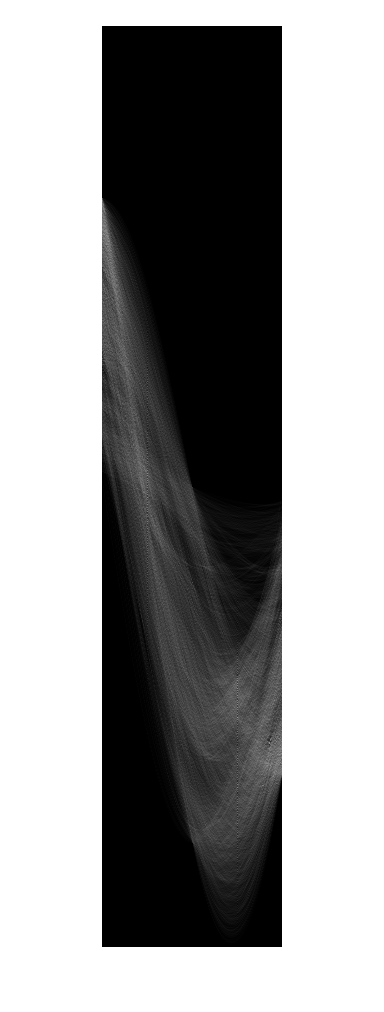

imshow(uint8(H));

d) Derive the equations to convert the [theta, radius] line representation to the normal line equation form *Ax + By = C **in image coordinates*. 

*---*

*Derive the equations*

normal line equation: $N\cdot \left\lbrack \left(x,y\right)-N\right\rbrack =0$

given $N=\left(\rho \;\cos \theta ,\rho \;\sin \theta \right)=\rho \left(\cos \theta ,\sin \theta \right)$,

rewrite equation as: $\rho \left(\cos \theta ,\sin \theta \right)\cdot \left\lbrack \left(x,y\right)-\rho \left(\cos \theta ,\sin \theta \right)\right\rbrack =0$

expand to: $\rho \left(\cos \theta \right)x-\rho^2 \cos^2 \theta +\rho \left(\sin \theta \right)y-\rho^2 \sin^2 \theta =0$

factorise to: $\left(\rho \cos \theta \right)x+\left(\rho \sin \theta \right)y=\rho^2 \left(\sin^2 \theta +\cos^2 \theta \right)=\rho^2$

($\rho$ can be factorised away, but then it will not be the same as the result of pol2cart())

---

Show that A and B can be obtained via

>> [A, B] = pol2cart(theta*pi/180, radius);

>> B = -B;

B needs to be negated because the y-axis is pointing downwards for image coordinates.

[A, B] = pol2cart(theta*pi/180, radius);
B = -B;

A % rho * cos(theta*pi/180)

A = 8.0281

B % -rho * sin(theta*pi/180)

B = -459.9299


cosTheta = cos(theta*pi/180);
sinTheta = sin(theta*pi/180);

A = radius * cosTheta

A = 8.0281

B = -radius * sinTheta

B = -459.9299

C = radius^2

C = 211600

% shown

Find C. Reminder: the Hough transform is done with respect to an origin at the centre of the image, and you will need to convert back to image coordinates where the origin is in the top-left corner of the image.

---

*Find C*

Let $\left(x_0 ,y_0 \right)$ be the same point as $\left(x,y\right)$, but with the top-left corner as the origin.

Let$\Delta x$ be difference between $x_0$ and $x$, $\Delta y$ be difference between $y_0$ and $y$.

substitute variables: $\left(\rho \mathrm{cos}\theta \right)\left(x_0 -\Delta x\right)+\left(\rho \mathrm{sin}\theta \right)\left(y_0 -\Delta y\right)=\rho^2$

expand to: $\left(\rho \mathrm{cos}\theta \right)x_0 \;+{\left(\rho \mathrm{sin}\theta \right)y}_0 =\rho^2 +\left(\rho \mathrm{cos}\theta \right)\Delta x+\left(\rho \mathrm{sin}\theta \right)\Delta y$

[imageHeight, imageWidth, imageChannels] = size(image)

imageHeight = 290

imageWidth = 358

imageChannels = 1

C = radius^2 % + A * imageWidth/2 + B * imageHeight/2

C = 211600

e) Based on the equation of the line Ax+By = C that you obtained, compute yl and yr values for corresponding xl = 0 and xr = width of image - 1.

xl = 0

xl = 0

yl = (C - A*(xl - imageWidth)) / B + imageHeight

yl = -176.3190

% yl = (C - A*xl) / B

xr = imageWidth - 1

xr = 357

yr = (C - A*(xr - imageWidth)) / B + imageHeight

yr = -170.0875

% yr = (C - A*xr) / B

f) Display the original ‘macritchie.jpg’ image. Superimpose your estimated line by

>> line([xl xr], [yl yr]);

Does the line match up with the edge of the running path? What are, if any, sources of errors? Can you suggest ways of improving the estimation?

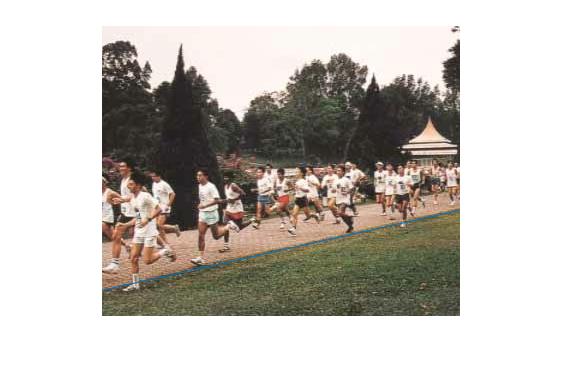

imshow(originalImage);
% line([xl, xr], [yl, yr]);
line([0, imageWidth - 1], [265, 185]);